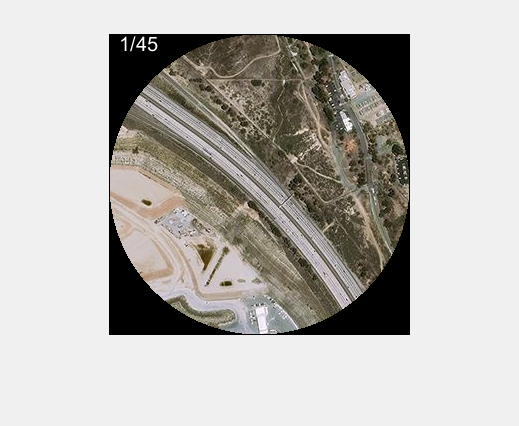

clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
counter=1;
for ii=1:nfiles
   currentfilename = imagefiles(ii).name;
   if currentfilename(1)==letter
       currentimage = imread(directory+currentfilename);
       images{counter} = currentimage;
       [~,imageNames{counter},~] = fileparts(currentfilename);
       counter=counter+1;
   end
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

neworder = randperm(length(images));
for i=1:length(images)
    images2{i} = images{neworder(i)};
end
images = images2;

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

fig = figure;
set(gcf,'Visible','on');

out = images{1};
thresh = 0.0005;
speedthresh = 0.01;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);

pltanim(out,stitched);


end_early = false;
default_points = 0.5;
for j=1:length(images)
    disp(j)
    points=default_points;
    finished = false;
    while ~finished
        confidences = zeros(length(images),3);
        for i=1:length(images)
            if stitched(i)==0
                [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, points, true);
                confidences(i,:)=[final_confidence,final_delta_x,final_delta_y];
                if confidences(i,1)>=speedthresh
                    break
                end
            end
        end
        if sum(confidences(:,1)>=thresh)~=0
            [v,ind]=max(confidences(:,1));
            disp(v)
            [out, valid] = merge_images(out, images{ind}, round(-confidences(ind,2)), round(-confidences(ind,3)));
            % imwrite(out, "Output/"+letter+"/Run3_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".png");
            if ~valid
                points=points+0.5
                if points>=3.5
                    finished=true;
                    end_early=true;
                end
            else
                points=default_points;
                stitched(ind)=1;
                pltanim(out,stitched);
            end
        else
            if points>=2
                finished=true;
                end_early=true;
            else
                points=points+0.5
                default_points=default_points+0.25
            end
        end
    end
    if end_early
        break
    end
end

     1



    0.0167



ans = 0.5858

    0.0692



ans = 0.7614

    0.0199



ans = 0.6752

    0.0606



ans = 0.5580

    0.0114



ans = 0.5810

    0.0913



ans = 0.8015

    0.0265



ans = 0.6865

    0.2428



ans = 0.8219

    0.1768



ans = 0.7970

    0.0106



ans = 1.2655

points = 1

    0.0308



ans = 0.8951

    0.0111



ans = 1.4318

points = 1

    0.2010



ans = 0.8387

    0.0412



ans = 0.7792

    0.1289



ans = 0.5046

    0.0194



ans = 0.7814

    0.3910



ans = 0.9910

    0.0492



ans = 0.6424

    0.0089



ans = 0.8490

    0.0436



ans = 0.3143

    0.0071



ans = 1.4226

points = 1

    0.0072



ans = 0.8030

    0.0071



ans = 0.7694

    0.0234



ans = 0.8596

    0.0067



ans = 1.4783

points = 1

    0.0072



ans = 0.6280

sum(stitched)
imageNames(~stitched)
pltanim(out,stitched);
text(10,30,"Done!","Color",[1,1,1]);
imwrite(out, "Output/"+letter+"/"+rand()+".png");

function [] = pltanim(out, stitched)
        imshow(out);
        text(10,10,""+sum(stitched)+"/"+length(stitched),"Color",[1,1,1]);
        drawnow();
end